fs= 64000;

As = 15;

f_cntral = [102.4,512,2560,12800];
f_pass = zeros(1,4);

for i= 1:3
    f_pass(i) = sqrt(f_cntral(i)*f_cntral(i+1))
end

f_pass =   228.9734         0         0         0


f_pass = 1.0e+03 *

    0.2290    1.1449         0         0


f_pass = 1.0e+03 *

    0.2290    1.1449    5.7243         0


f_pass(4)= fs/2;                    % Para el ultimo filtro pseudo pasaaltos, dejarlo como la frecuencia de nyquist reduce el orden







%===========Diseño de pasabajos 01
f_p1= f_pass(1)

f_p1 = 228.9734

f_s1= f_cntral(2)

f_s1 = 512


w_trBand1 = f_s1-f_p1;               %Width of the transition band
%============Harris aprox
N1 =ceil((fs/w_trBand1)*(As/22))  

N1 = 155


N1 =210                             % Valor hallado tras múltiples iteraciones

N1 = 210

%============Determinación de coef 
Wp1 = f_p1/(fs/2)                   %Se normaliza la frecuencia de paso dividiendo por la frecuencia de Nyquist

Wp1 = 0.0072

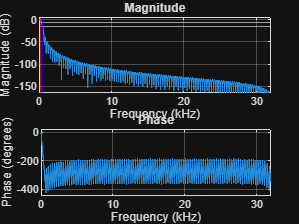

w_hann1 = hann(N1+1);                 % Creación de la ventana Hanning
B1 = fir1(N1,Wp1,"low",w_hann1);
    
%============Visualización
figure;
freqz(B1,1,2048,fs)
yline(-6)
yline(-15)
xline(f_p1/1000,'r')                          % Frecuencia de paso normalizada
xline(f_s1/1000,'b')                % Frecuencia de rechazo normalizad
xline(f_cntral(1),'r--')


%===========Diseño de pasabandas 02
f_p2L= f_pass(1)

f_p2L = 228.9734

f_s2L= f_cntral(1)

f_s2L = 102.4000

f_p2H= f_pass(2)

f_p2H = 1.1449e+03

f_s2H= f_cntral(3)

f_s2H = 2560




w_trBand2 = min(abs(f_p2L-f_s2L),  abs(f_s2H-f_p2H))              %Width of the transition band

w_trBand2 = 126.5734


%============Harris aprox
N2 =ceil(2*(fs/w_trBand2)*(As/22))  %Multiplicada por dos dado q es un pasabajos

N2 = 690


N2 =700                            % Valor hallado tras múltiples iteraciones

N2 = 700

%============Determinación de coef 
Wp2 = [f_p2L/(fs/2) f_p2H/(fs/2)]                    %Se normaliza la frecuencia de paso dividiendo por la frecuencia de Nyquist

Wp2 =     0.0072    0.0358


w_hann2 = hann(N2+1);                 % Creación de la ventana Hanning
B2 = fir1(N2,Wp2,"bandpass",w_hann2);

%============Visualización
figure;
freqz(B2,1,2048,fs)
yline(-6,'g--')
yline(-15,'v--')

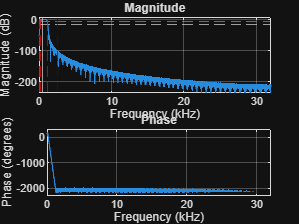

xline(f_p2H/1000,'r--')                          % Frecuencia de paso normalizada
xline(f_p2L/1000,'r--')

xline(f_s2L/1000,'b--')                % Frecuencia de rechazo normalizad
xline(f_s2H/1000,'b--')    
xline(f_cntral(2)/1000)


%===========Diseño de pasabandas 03
f_p3L= f_pass(2)

f_p3L = 1.1449e+03

f_s3L= f_cntral(2)

f_s3L = 512

f_p3H= f_pass(3)

f_p3H = 5.7243e+03

f_s3H= f_cntral(4)

f_s3H = 12800




w_trBand3 = min(abs(f_p3L-f_s3L),  abs(f_s3H-f_p3H))              %Width of the transition band, choose smallest width

w_trBand3 = 632.8668


%============Harris aprox
N3 =ceil(2*(fs/w_trBand3)*(As/22))  %Multiplicada por dos dado q es un pasabajos

N3 = 138


%N3 =700                            % Valor hallado tras múltiples iteraciones
%============Determinación de coef 
Wp3 = [f_p3L/(fs/2) f_p3H/(fs/2)]                    %Se normaliza la frecuencia de paso dividiendo por la frecuencia de Nyquist

Wp3 =     0.0358    0.1789


w_hann3 = hann(N3+1);                 % Creación de la ventana Hanning
B3 = fir1(N3,Wp3,"bandpass",w_hann3);

%============Visualización
figure;
freqz(B3,1,2048,fs)
yline(-6,'g--')
yline(-15,'v--')

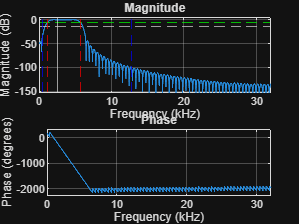

xline(f_p3H/1000,'r--')                          % Frecuencia de paso normalizada
xline(f_p3L/1000,'r--')

xline(f_s3L/1000,'b--')                % Frecuencia de rechazo normalizad
xline(f_s3H/1000,'b--')    
xline(f_cntral(3)/1000)


%===========Diseño de pasaaltos 04
f_p4= f_pass(3)

f_p4 = 5.7243e+03

f_s4= f_cntral(3)

f_s4 = 2560


w_trBand4 = abs(f_s4-f_p4);              %Width of the transition band
%============Harris aprox
N4 =ceil((fs/w_trBand4)*(As/22))  

N4 = 14


N4 =26                             % Valor hallado tras múltiples iteraciones

N4 = 26

%============Determinación de coef 
Wp4 = f_p4/(fs/2)                   %Se normaliza la frecuencia de paso dividiendo por la frecuencia de Nyquist

Wp4 = 0.1789

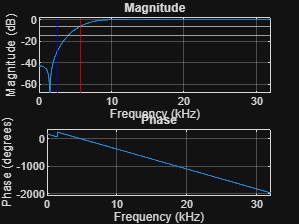

w_hann4 = hann(N4+1);                 % Creación de la ventana Hanning
B4 = fir1(N4,Wp4,'high',w_hann4);
    
%============Visualización
figure;
freqz(B4,1,2048,fs)
yline(-6)
yline(-15)
xline(f_p4/1000,'r')                          % Frecuencia de paso normalizada
xline(f_s4/1000,'b')                % Frecuencia de rechazo normalizad
xline(f_cntral(4),'r--')

% Cuarto Punto
t = 0:1/fs:1; % Tiempo de 1 segundo


[X, fs] = audioread("Ikkimel_WHOS_THAT.wav");   % audio File


if size(X,2) > 1
    X = mean(X, 2);% Convert to mono
end

%X = sin(2*pi*1000*t); % Señal de entrada (1 kHz)
%X = randn(64000,1);  % white Gaussian noise
%X = zeros(64000,1);% Impulse
%X(1) = 1;



% Sistema con filtros FIR

Nfft = 4096; % resolución de 15.625 Hz

y1 = fftfilt(B1,X,Nfft);
y2 = fftfilt(B2,X,Nfft);
y3 = fftfilt(B3,X,Nfft);
y4 = fftfilt(B4,X,Nfft);


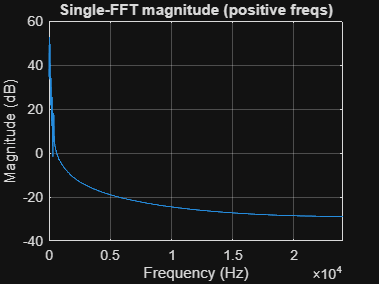


Y1 = fft(y1, Nfft);     % compute fft (zero-pad or trim to Nfft)
half = 1:floor(Nfft/2)+1;

f = (0:Nfft-1)*(fs/Nfft);      % frequency vector (0..fs)
f_pos = f(half);               % positive frequencies 0..fs/2

mag = abs(Y1(half));            % magnitude
mag_db = 20*log10(mag + eps);  % convert to dB, add eps to avoid log(0)

figure;
plot(f_pos, mag_db);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Single-FFT magnitude (positive freqs)');
grid on;
xlim([0 fs/2]);

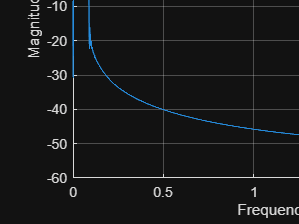

Y2 = fft(y2, Nfft);     % compute fft (zero-pad or trim to Nfft)
half = 1:floor(Nfft/2)+1;

f = (0:Nfft-1)*(fs/Nfft);      % frequency vector (0..fs)
f_pos = f(half);               % positive frequencies 0..fs/2

mag = abs(Y2(half));            % magnitude
mag_db = 20*log10(mag + eps);  % convert to dB, add eps to avoid log(0)

figure;
plot(f_pos, mag_db);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Single-FFT magnitude (positive freqs)');
grid on;
xlim([0 fs/2]);

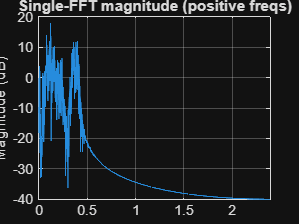


Y3 = fft(y3, Nfft);     % compute fft (zero-pad or trim to Nfft)
half = 1:floor(Nfft/2)+1;

f = (0:Nfft-1)*(fs/Nfft);      % frequency vector (0..fs)
f_pos = f(half);               % positive frequencies 0..fs/2

mag = abs(Y3(half));            % magnitude
mag_db = 20*log10(mag + eps);  % convert to dB, add eps to avoid log(0)

figure;
plot(f_pos, mag_db);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Single-FFT magnitude (positive freqs)');
grid on;
xlim([0 fs/2]);

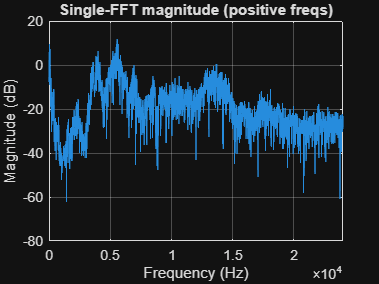

Y4 = fft(y4, Nfft);     % compute fft (zero-pad or trim to Nfft)
half = 1:floor(Nfft/2)+1;

f = (0:Nfft-1)*(fs/Nfft);      % frequency vector (0..fs)
f_pos = f(half);               % positive frequencies 0..fs/2

mag = abs(Y4(half));            % magnitude
mag_db = 20*log10(mag + eps);  % convert to dB, add eps to avoid log(0)

figure;
plot(f_pos, mag_db);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Single-FFT magnitude (positive freqs)');
grid on;
xlim([0 fs/2]);

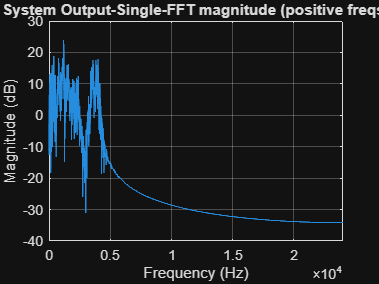

% Ganacia 

G1 = 0;
G2 = 0.2;
G3 = 2;
G4 = 0;

y_final = y1*G1 + y2*G2 + y3*G3 + y4*G4;


Y_final = fft(y_final, Nfft);     % compute fft (zero-pad or trim to Nfft)
half = 1:floor(Nfft/2)+1;

f = (0:Nfft-1)*(fs/Nfft);      % frequency vector (0..fs)
f_pos = f(half);               % positive frequencies 0..fs/2

mag = abs(Y_final(half));            % magnitude
mag_db = 20*log10(mag + eps);  % convert to dB, add eps to avoid log(0)

figure;
plot(f_pos, mag_db);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('System Output-Single-FFT magnitude (positive freqs)');
grid on;
xlim([0 fs/2]);

% Normalize to prevent clipping (optional but safe)
y_final = y_final / max(abs(y_final));

% Save filtered output to a new audio file
audiowrite("ikkimelDone.wav", y_final, fs);

disp("Done! File saved as output_filtered.wav");

Done! File saved as output_filtered.wav
